# Thermal Modeling

First, the model Thermal distributions are modeled based on Figure 4 in K.H. Horstmann "New model Thermal distributions and their influence on interpretation of gliders"

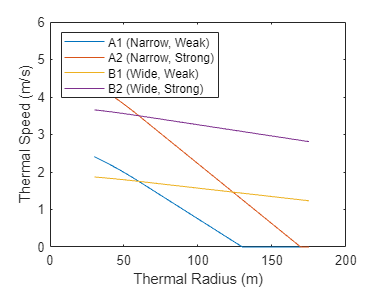

clc
clear all

% Thermal distributions based at a radius of 60 m
L_Dmax = 46.5; % L/D max
A = 22.82; % Aspect Ratio
e = 0.9; % Oswald efficiency factor
rho = 1.225; % Sea level density kg/m^3
phi = (pi ./ 180) .* [20 25 30 35 40 45 50]; % Roll angle in rad Per Horstmann from experience: 45deg-49deg good for tight thermals, 29deg-34deg goood for wide thermals
W2S = [250 300 350 400 450 500 550]; % Wing loading N/m^2
r = 30:175; % Turn radius m
g = 9.81; % Acceleration due to gravity m/s^2
C_D_0 = .00829;
C_L = 1.6;
A = 20;
g = 9.81;

V_T = HorstmannThermal(r);

figure
plot(r,V_T(1,:))
hold on
plot(r,V_T(2,:))
plot(r,V_T(3,:))
plot(r,V_T(4,:))

xlim([0,200])
ylim ([0,6])

xlabel("Thermal Radius (m)")
ylabel("Thermal Speed (m/s)")
legend('A1 (Narrow, Weak)','A2 (Narrow, Strong)','B1 (Wide, Weak)','B2 (Wide, Strong)', Location="northwest")

hold off



% Sink Rate
% see eqn 78 in fundamentals of sailplane design
% Use various bank angles and wing loadings
C_Lmax = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
C_Dmax = 2 * (C_Lmax^2)/(pi * A * e); % Maximum drag coefficient

% Find sink rates at different wing loadings
V_sc = Vsinkrate(C_D_0, C_L, A, e, r, g, rho, W2S); % Sink rate m/s

% Find sink rates from optimal roll angles in different thermals
V_sc_phi = Vsinkrate_phi(C_Dmax, C_Lmax, phi, rho, W2S); %Sink rates at different wing loadings (rows) and at different roll angles (columns)

% Find climb rates in different thermals for various wing loadings 

[V_ca1, V_ca2, V_cb1, V_cb2] = Vclimbspeed(V_T, V_sc);


figure;

%subplot(2,2,1)
plot(r,V_sc(1,:))
hold on
 for i = 1:7
     plot(r,V_sc(i,:));
 end

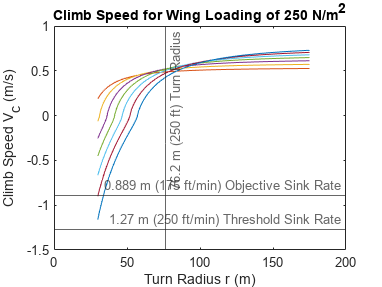



title('Climb Speed for Wing Loading of 250 N/m^2')
%ylim([0,4])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
%legend('A1','A2','B1','B2', Location="southwest")
hold off


figure;

subplot(2,2,1)
plot(r,V_ca1(1,:))
hold on

plot(r,V_ca2(1,:))
plot(r,V_cb1(1,:))
plot(r,V_cb2(1,:))

title('Climb Speed for Wing Loading of 250 N/m^2')
ylim([0,4])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
%legend('A1','A2','B1','B2', Location="southwest")
hold off

subplot(2,2,2)
plot(r,V_ca1(2,:))

hold on

plot(r,V_ca2(2,:))

plot(r,V_cb1(2,:))

plot(r,V_cb2(2,:))


title('Climb Speed for Wing Loading of 300 N/m^2')
ylim([0,3.75])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off

subplot(2,2,3)
plot(r,V_ca1(3,:))

hold on

plot(r,V_ca2(3,:))

plot(r,V_cb1(3,:))

plot(r,V_cb2(3,:))


title('Climb Speed for Wing Loading of 350 N/m^2')
ylim([0,3.75])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off

subplot(2,2,4)
plot(r,V_ca1(4,:))

hold on

plot(r,V_ca2(4,:))

plot(r,V_cb1(4,:))

plot(r,V_cb2(4,:))

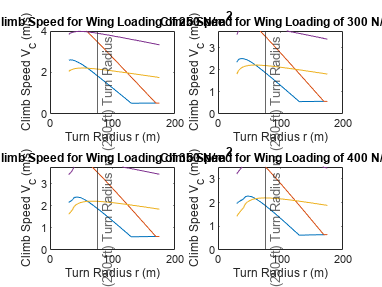


title('Climb Speed for Wing Loading of 400 N/m^2')
ylim([0,3.5])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off


figure;

subplot(2,2,1)
plot(r,V_ca1(5,:))

hold on

plot(r,V_ca2(5,:))

plot(r,V_cb1(5,:))

plot(r,V_cb2(5,:))


title('Climb Speed for Wing Loading of 450 N/m^2')
ylim([0,3.5])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off

subplot(2,2,2)
plot(r,V_ca1(6,:))

hold on

plot(r,V_ca2(6,:))

plot(r,V_cb1(6,:))

plot(r,V_cb2(6,:))


title('Climb Speed for Wing Loading of 500 N/m^2')
ylim([0,3.5])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off

subplot(2,2,3)
plot(r,V_ca1(7,:))

hold on

plot(r,V_ca2(7,:))

plot(r,V_cb1(7,:))

plot(r,V_cb2(7,:))

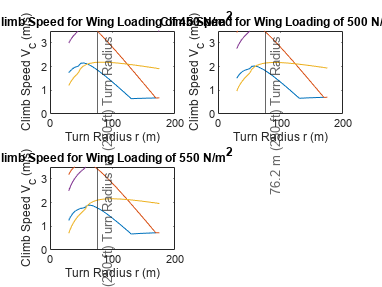


title('Climb Speed for Wing Loading of 550 N/m^2')
ylim([0,3.5])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed V_c (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
hold off